# Omission GLO analysis

HNXJ@github

clear;clc;close all;

cd('D:\Electrophysiology\Matdelane\');
addpath(genpath('matnwb'));
addpath(genpath('matdelane'));
generateCore();

addpath('fieldtrip');ft_defaults;
nwbPath = "data\";

nwbFiles = {dir(nwbPath).name};
nwbFiles = nwbFiles(endsWith(nwbFiles, ".nwb"));

disp("Toolbox setup done.");

Toolbox setup done.


I. Load all areas

nPath = "neuronData\";
nFiles = {dir(nPath).name};
nFiles = nFiles(endsWith(nFiles, ".mat"));

z = cell(1, 10);

for i = 1:10

    nFile = nFiles{i};
    z{i} = load(nPath + nFile).z;
    disp(num2str(i) + ". loaded : " + nFile);

end

1. loaded : 01_Neurons_OGLO_V1.mat
2. loaded : 02_Neurons_OGLO_V2.mat
3. loaded : 03_Neurons_OGLO_V3d.mat
4. loaded : 04_Neurons_OGLO_V3a.mat
5. loaded : 05_Neurons_OGLO_V4.mat
6. loaded : 06_Neurons_OGLO_TEO.mat
7. loaded : 07_Neurons_OGLO_MT.mat
8. loaded : 08_Neurons_OGLO_MST.mat
9. loaded : 09_Neurons_OGLO_FEF.mat
10. loaded : 10_Neurons_OGLO_PFC.mat


areaNames = cell(1, 10);
areaCounts = zeros(1, 10);

for k = 1:10    

    areaName = strsplit(nFiles{k}, '_');
    areaNames{k} = areaName{end}(1:end-4);
    cnt = 0;

    for l = 1:size(z{k}{1}, 2)

        cnt = cnt + size(z{k}{1}{l}, 2);

    end

    areaCounts(k) = cnt;

end

Temporal PEV : RRRR vs shuffle

cond1 = 9;
expvar = cell(1, 10);

for k = 1:10

    ntotal = 0;
    expvar{k} = zeros(size(z{k}{1}, 2), 6000);

    for l = 1:size(z{k}{1}, 2)

        x1 = z{k}{cond1}{l}(:, :, mod(randperm(6000, 6000), 1000)+1);
        x2 = z{k}{cond1}{l}(:, :, 1:6000);
        
        N = min(size(x1, 1), size(x2, 1));
        n1 = size(x1, 2);
    
        idx1 = randperm(size(x1, 1), N);
        idx2 = randperm(size(x2, 1), N);
        
        x1 = squeeze(mean(x1(idx1, :, :), 1));
        x2 = squeeze(mean(x2(idx2, :, :), 1));
        
        data = [x2; x1];
        groupIDs = [ones(1, n1), ones(1, n1)*2];

        try

            data = jMeanFilt2(data, 1, 50);
            [expvar{k}(l, :), n, mu, p, F] = jPEV(data, groupIDs, 1);

        catch

            if n1 == 1
                data = [x2'; x1'];
                [expvar{k}(l, :), n, mu, p, F] = jPEV(data, groupIDs, 1);
                fprintf(num2str(k));
            end

        end

        ntotal = n1 + ntotal;

    end

end

1

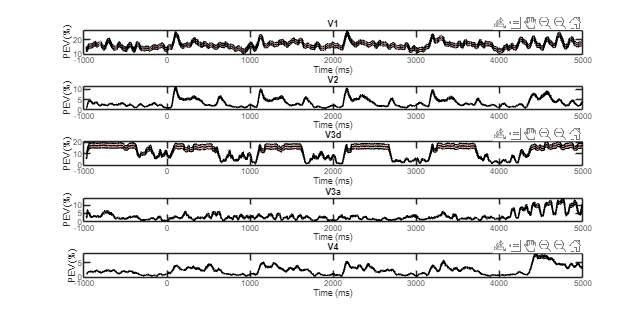

% figure("Position", [0 0 2000 1000]);
cl = [0.9 0.7 0.7];

for k = 1:10

    % subplot(5, 1, k);
    figure("Position", [0 0 1500 500]);
    t = linspace(-970, 5030, 6000);
    yt = smooth(squeeze(mean(expvarx{9, k}, 1)), 10)*100;
    st = smooth(squeeze(std(expvarx{9, k}, 1)), 50)*100/sqrt(areaCounts(k));
    stx = smooth(yt + st, 20);
    sty = smooth(yt - st, 20);
    plot(t, stx, "Color", cl);
    hold("on");
    plot(t, sty, "Color", cl);
    patch([t, t(end:-1:1)], [stx;sty(end:-1:1)], cl);
    plot(t, yt, "Color", "k");

    % xline(-500, "HandleVisibility", "off", "Color", "g");
    % xline(0, "HandleVisibility", "off", "Color", "r");
    % xline(1030, "HandleVisibility", "off", "Color", "r");
    % xline(2060, "HandleVisibility", "off", "Color", "r");
    % xline(3090, "HandleVisibility", "off", "Color", "r");

    title(areaNames{k});
    xlabel("Time (ms)");
    ylabel("PEV (%)");
    xlim([-1000 5000]);

end

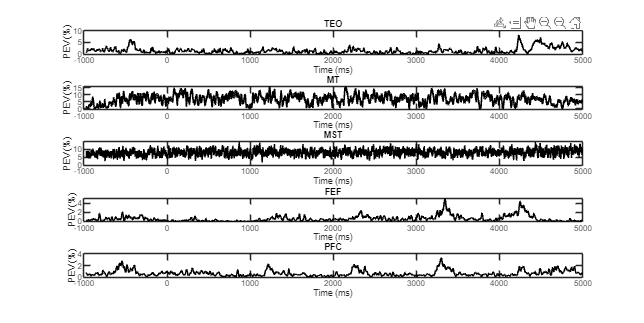

figure("Position", [0 0 2000 1000]);
cl = [0.9 0.7 0.7];

for k = 6:10

    subplot(5, 1, k-5);
    t = linspace(-970, 5030, 6000);
    yt = smooth(squeeze(mean(expvar{9, k}, 1)), 10)*100;
    st = smooth(squeeze(std(expvar{9, k}, 1)), 100)*100/sqrt(areaCounts(k));
    plot(t, yt + st, "Color", cl);
    hold("on");
    plot(t, yt - st, "Color", cl);
    patch([t, t(end:-1:1)], [yt + st; yt(end:-1:1) - st(end:-1:1)], cl);
    plot(t, yt, "Color", "k");

    % xline(-500, "HandleVisibility", "off", "Color", "g");
    % xline(0, "HandleVisibility", "off", "Color", "r");
    % xline(1030, "HandleVisibility", "off", "Color", "r");
    % xline(2060, "HandleVisibility", "off", "Color", "r");
    % xline(3090, "HandleVisibility", "off", "Color", "r");

    title(areaNames{k});
    xlabel("Time (ms)");
    ylabel("PEV (%)");
    xlim([-1000 5000]);

end

## I. Omission population PEVs

All conditions / sMUA

conds = 1:12;

expvar = cell(12, 10);

for k = 1:10

    fprintf("\n Area : " + areaNames{k});

    for kl = 1:12

        ntotal = 0;
        expvar{kl, k} = zeros(size(z{k}{1}, 2), 6000);
    
        for l = 1:size(z{k}{1}, 2)
    
            x1 = z{k}{conds(kl)}{l}(:, :, mod(randperm(6000, 6000), 1000)+1);
            x2 = z{k}{conds(kl)}{l}(:, :, 1:6000);
            
            N = min(size(x1, 1), size(x2, 1));
            n1 = size(x1, 2);
        
            idx1 = randperm(size(x1, 1), N);
            idx2 = randperm(size(x2, 1), N);
            
            x1 = squeeze(mean(x1(idx1, :, :), 1));
            x2 = squeeze(mean(x2(idx2, :, :), 1));
            
            data = [x2; x1];
            groupIDs = [ones(1, n1), ones(1, n1)*2];
    
            if n1 > 1

                data = jMeanFilt2(data, 1, 10);
                [expvar{kl, k}(l, :), n, mu, p, F] = jPEV(data, groupIDs, 1);

            elseif n1 == 1

                data = [x2'; x1'];
                [expvar{kl, k}(l, :), n, mu, p, F] = jPEV(data, groupIDs, 1);
                fprintf(num2str(k) + "|");

            else

                fprintf(num2str(k) + "-");

            end
    
            ntotal = n1 + ntotal;
    
        end

    end

end


 Area : MST

8-8-8-8-8-8-8-8-8-8-8-8-8-8-8-8-8-8-8-8-8-8-8-8-

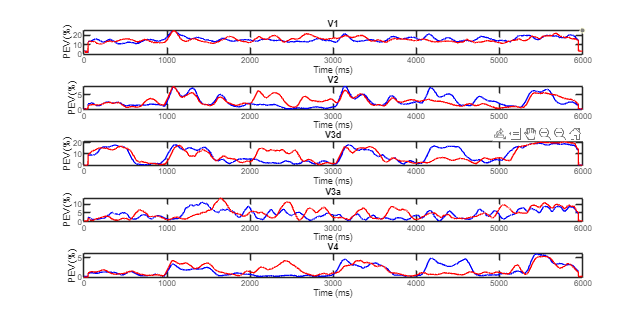

figure("Position", [0 0 2000 1000]);
cl = [0.9 0.7 0.7];

for k = 1:10

    subplot(5, 1, k);
    % figure("Position", [0 0 1500 500]);
    t = linspace(-970, 5030, 6000);
    yt = smooth(squeeze(mean(expvarx{9, k}, 1)), 10)*100;
    st = smooth(squeeze(std(expvarx{9, k}, 1)), 50)*100/sqrt(areaCounts(k));
    stx = smooth(yt + st, 20);
    sty = smooth(yt - st, 20);
    plot(t, stx, "Color", cl);
    hold("on");
    plot(t, sty, "Color", cl);
    patch([t, t(end:-1:1)], [stx;sty(end:-1:1)], cl);
    plot(t, yt, "Color", "k");

    title(areaNames{k});
    xlabel("Time (ms)");
    ylabel("PEV (%)");
    xlim([-1000 5000]);

end

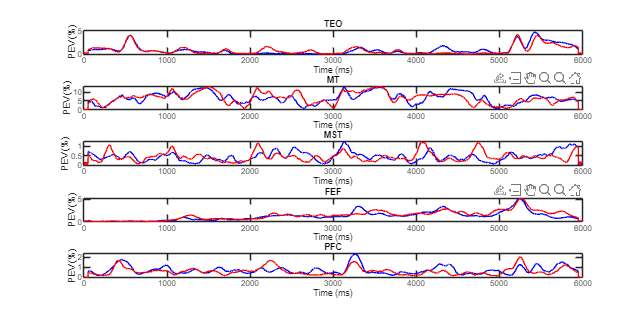

figure("Position", [0 0 2000 1000]);
cl = [0.9 0.7 0.7];
oc = 5;

for k = oc+1:oc+5

    subplot(5, 1, k-oc);
    % t = linspace(3000, 4000, 1000);
    yt1 = jMeanFilt2(expvar{1, k}, 1, 50)*100;
    yt2 = jMeanFilt2(expvar{3, k}, 1, 50)*100;
    plot(mean(yt1, 1), "b");hold("on");plot(mean(yt2, 1), "r");

    % hold("on");grid("on");
    % plot(t, yt - st, "Color", cl);
    % patch([t, t(end:-1:1)], [yt + st; yt(end:-1:1) - st(end:-1:1)], cl);
    % plot(t, yt, "Color", "k");
    % 
    % xline(-500, "HandleVisibility", "off", "Color", "g");
    % xline(0, "HandleVisibility", "off", "Color", "r");
    % xline(1030, "HandleVisibility", "off", "Color", "r");
    % xline(2060, "HandleVisibility", "off", "Color", "r");
    % xline(3090, "HandleVisibility", "off", "Color", "r");
    % 
    title(areaNames{k});
    xlabel("Time (ms)");
    ylabel("PEV (%)");
    % xlim([3000 4000]);

end

## II. Omission single PEVs

All conditions / SUA

conds = 1:12;

expvarx = cell(12, 10);

for k = 1:10

    fprintf("\n Area : " + areaNames{k});

    for kl = 1:12

        ntotal = 0;
        expvarx{kl, k} = zeros(1, 6000);
    
        for l = 1:size(z{k}{1}, 2)
    
            x1 = z{k}{conds(kl)}{l}(:, :, mod(randperm(6000, 6000), 500)+1);
            x2 = z{k}{conds(kl)}{l}(:, :, 1:6000);
            
            N = min(size(x1, 1), size(x2, 1));
            n1 = size(x1, 1);
            n2 = size(x1, 2);
        
            idx1 = randperm(size(x1, 1), N);
            idx2 = randperm(size(x2, 1), N);
            
            % x1 = squeeze(mean(x1(idx1, :, :), 1));
            % x2 = squeeze(mean(x2(idx2, :, :), 1));
            
            data = [x2; x1];
            groupIDs = [ones(1, n1), ones(1, n1)*2];
    
            if n1 > 1

                % data = jMeanFilt2(data, 1, 10);
                [expvarx{kl, k}(ntotal+1:ntotal+n2, :), n, mu, p, F] = jPEV(data, groupIDs, 1);

            elseif n1 == 1

                data = [x2; x1];
                [expvarx{kl, k}(ntotal+1:ntotal+n2, :), n, mu, p, F] = jPEV(data, groupIDs, 1);
                fprintf(num2str(k) + "|");

            else

                fprintf(num2str(k) + "-");

            end
    
            ntotal = n2 + ntotal;
    
        end

    end

end


 Area : V1

1|


 Area : V2

2|


 Area : V3d

3|


 Area : V3a

4|


 Area : V4

5-5-5-5-


 Area : TEO

6-6-6-6-


 Area : MT

7-7-7-7-


 Area : MST

8-8-8-8-


 Area : FEF

9-9-9-9-


 Area : PFC

10-10-10-10-

scorex = cell(1, 10);

for k = 1:10

    scorex{k} = zeros(1, areaCounts(k));
    ncount = 0;

    for l = 1:size(z{k}{1}, 2)

        yt1 = squeeze(mean(z{k}{1}{l}, 1));
        yt2 = squeeze(mean(z{k}{2}{l}, 1));
        yt3 = squeeze(mean(z{k}{3}{l}, 1));
        yt4 = squeeze(mean(z{k}{4}{l}, 1));

        N = size(yt1, 1);
        Nx = size(yt1, 2);

        if Nx == 6000

            scoresx = ((mean(yt2(:, 2001:3000), 2) + mean(yt3(:, 3001:4000), 2) + mean(yt4(:, 4001:5000), 2))/3) ./ mean(yt1(:, 1001:2000), 2);
            scorex{k}(ncount+1:ncount+N) = scoresx;
            ncount = ncount + N;

        elseif Nx == 1

            scoresx = ((mean(yt2(2001:3000)) + mean(yt3(3001:4000)) + mean(yt4(4001:5000)))/3) ./ mean(yt1(1001:2000));
            scorex{k}(ncount+1:ncount+Nx) = scoresx;
            ncount = ncount + Nx;

        end

    end

    fprintf(num2str(k) + "-");

end

1-2-3-4-5-6-7-8-9-10-

scorex = cell(1, 10);

for k = 1:10

    scorex{k} = zeros(12, areaCounts(k));
    ncount = 0;

    for l = [1, 5, 9]

        yt1 = expvarx{l, k};
        scoresx = max(yt1(:, 1001:1600));
        scorex{k}(l, 1:length(scoresx)) = scoresx;

    end

    for l = [2, 6, 10]

        yt1 = expvarx{l, k};
        scoresx = max(yt1(:, 2001:2600));
        scorex{k}(l, 1:length(scoresx)) = scoresx;

    end

    for l = [3, 7, 11]

        yt1 = expvarx{l, k};
        scoresx = max(yt1(:, 3001:3600));
        scorex{k}(l, 1:length(scoresx)) = scoresx;

    end

    for l = [4, 8, 12]

        yt1 = expvarx{l, k};
        scoresx = max(yt1(:, 4001:4600));
        scorex{k}(l, 1:length(scoresx)) = scoresx;

    end

    fprintf(num2str(k) + "-");

end

1-2-3-4-5-6-7-8-9-10-

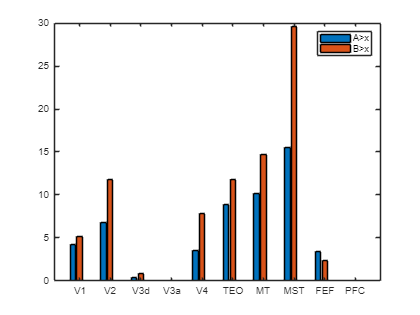

xpref = zeros(3, 10);

for i = 1:10

    aap = scorex{i}(1, :);
    bbp = scorex{i}(5, :);
    rrp = scorex{i}(5, :);
    xxp = scorex{i}(2, :);
    xxp2 = scorex{i}(12, :);

    axx = ((scorex{i}(1, :)-scorex{i}(3, :))./(scorex{i}(1, :)+scorex{i}(3, :)));
    bxx = ((scorex{i}(5, :)-scorex{i}(7, :))./(scorex{i}(5, :)+scorex{i}(7, :)));
    rxx = ((scorex{i}(9, :)-scorex{i}(11, :))./(scorex{i}(9, :)+scorex{i}(11, :)));
    % axx = axx(~isnan(axx));
    % bxx = bxx(~isnan(bxx));
    % rxx = rxx(~isnan(rxx));
    axp = aap > (xxp2);% | (xxp ~= 0);
    bxp = bbp > (xxp2);% | (xxp ~= 0);
    cxp = xxp2 > rrp & xxp2 > aap & xxp2 > bbp;
    N = numel(axp);

    xpref(1, i) = sum(axp)/N;
    xpref(2, i) = sum(bxp)/N;
    xpref(3, i) = 0*sum(cxp)/N;

end
figure;
bar(areaNames, 100*xpref');
legend("A>x", "B>x")

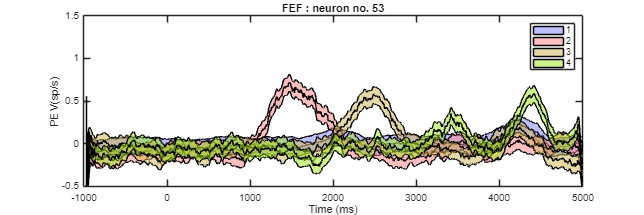

areaX = 9;
neuronX = 53;
condX = [1, 2, 3, 4];
jOmissionPEVPlot(expvarx, areaX, neuronX, condX, areaNames);

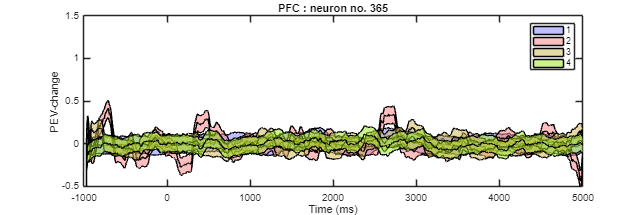

areaX = 10;
neuronX = 365;
condX = [1, 2, 6, 12];
jOmissionPEVPlot(expvarx, areaX, neuronX, condX, areaNames);

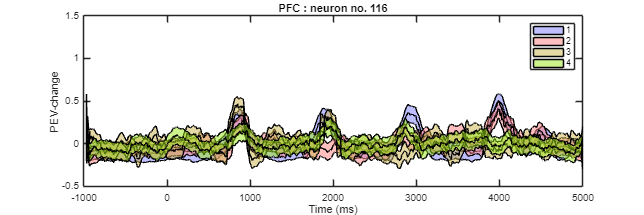

areaX = 10;
neuronX = 116;
condX = [1, 2, 3, 4];
jOmissionPEVPlot(expvarx, areaX, neuronX, condX, areaNames);

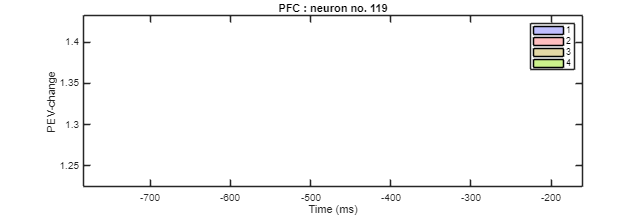

areaX = 10;
neuronX = 119;
condX = [1, 2, 3, 4];
jOmissionPEVPlot(expvarx, areaX, neuronX, condX, areaNames);

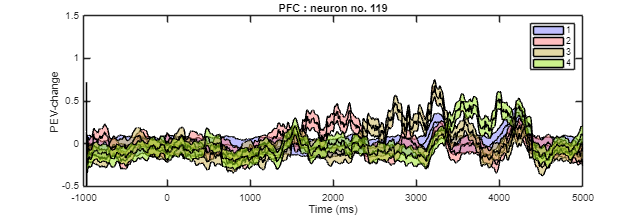

areaX = 10;
neuronX = 119;
condX = [5, 6, 7, 8];
jOmissionPEVPlot(expvarx, areaX, neuronX, condX, areaNames);

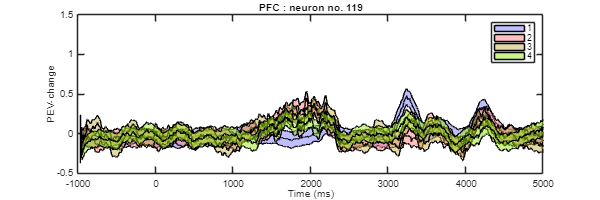

areaX = 10;
neuronX = 119;
condX = [1, 2, 6, 10];
jOmissionPEVPlot(expvarx, areaX, neuronX, condX, areaNames);

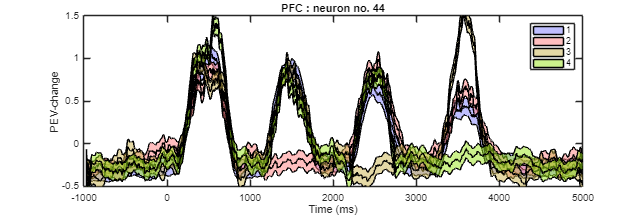

areaX = 10;
neuronX = 44;
condX = [1, 2, 3, 4];
jOmissionPEVPlot(expvarx, areaX, neuronX, condX, areaNames);

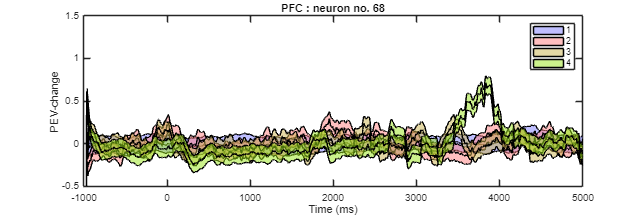

areaX = 10;
neuronX = 68;
condX = [1, 2, 3, 4];
jOmissionPEVPlot(expvarx, areaX, neuronX, condX, areaNames);

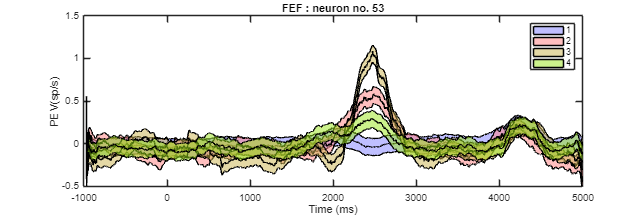

areaX = 9;
neuronX = 53;
condX = [1, 3, 7, 11];
jOmissionPEVPlot(expvarx, areaX, neuronX, condX, areaNames);

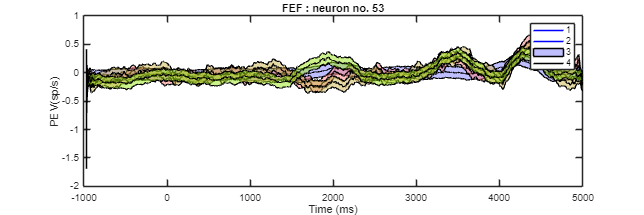

areaX = 9;
neuronX = 53;
condX = [1, 4, 8, 12];
jOmissionPEVPlot(expvarx, areaX, neuronX, condX, areaNames);

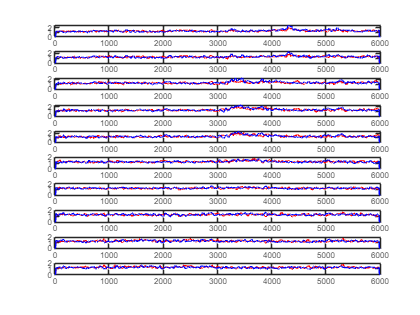

imx = jMeanFilt2(expvarx{3, 9}, 1, 20)*100;
imy = jMeanFilt2(expvarx{7, 9}, 1, 20)*100;
figure;
for neuronx = 41:50
    subplot(10, 1, mod(neuronx-1, 10) + 1);
    imxx = smooth(imx(neuronx, :), 10);
    plot(imxx, "r");
    hold("on");
    imyy = smooth(imy(neuronx, :), 10);
    plot(imyy, "b");
end

## Conditional-comparative PEVs

PEV(A) ? PEV(B) ?PEV(R)

    Stimulus specific and non-specific preferences

(PEV(A),PEV(B),PEV(R)) ? PEV(X)

    Non-specific omission preferences

PEV(X|A) ? PEV(X|B) ? PEV(X|R)

    Specific omission preferences

neuronCount = zeros(1, 10);
neuronSPEVcnt = zeros(1, 10);
cond1 = 12;
cond2 = 9;

for k = 1:10

    for l = 1:size(z{k}{cond1}, 2)
        x1 = z{k}{cond1}{l}(:, :, 3501:4500);
        x2 = z{k}{cond2}{l}(:, :, 501:1500);
        
        idx1 = randperm(size(x1, 1), min(100, size(x1, 1)));
        idx2 = randperm(size(x2, 1), min(100, size(x2, 1)));
        
        x1 = x1(idx1, :, :);
        x2 = x2(idx2, :, :);

        data1 = squeeze(mean(x1, 1));
        data2 = squeeze(mean(x2, 1));

        % data1 = x1;
        % data2 = x2;

        try
            data1 = jMeanFilt2(data1, 1, 50);
            data2 = jMeanFilt2(data2, 1, 50);
    
            groupIDs = [ones(1, 500), ones(1, 500)*2];
            [expVar1, n, mu, p, F] = jPEV(data1, groupIDs, 2);
            [expVar2, n, mu, p, F] = jPEV(data2, groupIDs, 2);
    
            expVar1 = mean(expVar1, 1);
            expVar2 = mean(expVar2, 1);
            neuronCount(k) = neuronCount(k) + size(expVar1, 2);
            neuronSPEVcnt(k) = neuronSPEVcnt(k) + sum(expVar1 > 2*expVar2);
        catch
        end
    end

end

neuronCount5 = neuronCount;
neuronSPEVcnt5 = neuronSPEVcnt;

figure("Position", [0 0 1500 1000]);

% subplot(4, 1, 1);
% bar(areaNames, [neuronCount1; neuronSPEVcnt1]);
% title("A pref.");
% xlabel("Area");
% ylabel("N");
% legend("Total count", "Stim. A PEV > 5%");
% 
% subplot(4, 1, 2);
% bar(areaNames, [neuronCount2; neuronSPEVcnt2]);
% title("B pref.");
% xlabel("Area");
% ylabel("N");
% legend("Total count", "Stim. B PEV > 5%");
% 
% subplot(4, 1, 3);
% bar(areaNames, neuronSPEVcnt3./neuronCount3*100);
% title("A or B pref.");
% xlabel("Area");
% ylabel("N");
% ylim([0 100]);
% legend("Stim. responsive ratio %");
subplot(1, 1, 1);
bar(areaNames, neuronSPEVcnt5./neuronCount5*100);
title("X vs R pref.");
xlabel("Area");
ylabel("% of N");
ylim([0 100]);
legend("X explains more than R");

## Approximate entropy analysis

In statistics, an approximate entropy (ApEn) is a technique used to quantify the amount of regularity and the unpredictability of fluctuations over time-series data.

apxn = 1.8253

apxn = 0.0265

## Appendix A

### A0. Identifiy areas

Nfile = numel(nwbFiles);
c = cell(1, Nfile);
x = cell(1, Nfile);

for k = 1:Nfile

    nwbFile = nwbPath + nwbFiles{k};
    nwb = nwbRead(nwbFile);
    [c{k}, x{k}] = jOGLOUnits(nwb, "omission_glo_passive", 1000, 5000, 0);

end

5 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
5 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
5 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
6 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
5 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
5 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
5 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
5 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
6 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
4 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
->Kilosort2.0: Single unit neurons were not detected in this probe.
4 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
4 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
5 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
4 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
4 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.


% save("xspk.mat", "x", "-v7.3");save("cspk.mat", "c", "-v7.3");

% load("x.mat");load("c.mat");

### A1. Organize by area

areas = ["V1", "V2", "V3a", "V3d", "V4", "MT", "MST", "TEO", "FEF", "PFC"];
y = cell(10, 12);

for k = 1:numel(c)

    fprintf("%d-", k);
    for l = 1:numel(c{k})

        if strcmpi(c{k}{l}.name, "V3")
            m = 2;
        else
            m = find(strcmpi(c{k}{l}.name, areas));
        end
        
        try
    
            for j = 1:12
    
                sig = x{k}{j};
                y{m, j}{end + 1} = sig(:, c{k}{l}.ids, :);
    
            end

        catch

        end

    end

end

1-2-3-4-5-6-7-8-9-10-11-12-13-14-15-16-

for i = 1:11

    cnt = 0;

    for j = 1:size(y{i, 1}, 2)

        cnt = cnt + size(y{i, 1}{j}, 2);

    end

    fprintf(areas(i) + " : %d\n", cnt);

end

for i = 1:10

    z = cell(1, 12);

    for j = 1:12
        z{j} = y{i, j};
    end

    save("neuronData\SPK_" + num2str(i) + "_Neurons_OGLO_" + areas(i), "z", "-v7.3");

end

## Appendix B

### B0. Identifiy areas

Nfile = numel(nwbFiles);
c = cell(1, Nfile);
x = cell(1, Nfile);

kcnt = 1;

for k = 1:5 % Nfile

    nwbFile = nwbPath + nwbFiles{k};
    nwb = nwbRead(nwbFile);

    for kl = 1:length(nwb.general_extracellular_ephys.keys())
    
        [c{kcnt}, x{kcnt}] = jOGLOSignals(nwb, "omission_glo_passive", 1000, 5000, kl-1);
        kcnt = kcnt + 1;

    end

    disp("Processed : " + nwbFile);

end

1 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
2 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
2 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
1 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
2 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
2 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
1 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
2 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
2 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
1 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
2 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
3 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
1 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
2 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
2 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
1 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
2 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.
2 areas identified.
1 2 3 4 5 6 7 8 9 10 11 12 
Done.


% save("xl.mat", "x", "-v7.3");save("cl.mat", "c", "-v7.3");

% load("xl.mat");load("cl.mat");

### B1. Organize by area

areas = ["V1", "V2", "V3a", "V3d", "V4", "MT", "MST", "TEO", "FEF", "PFC"];
y = cell(11, 12);

for k = 1:numel(c)

    fprintf("%d-", k);
    for l = 1:numel(c{k})

        m = find(strcmpi(c{k}{l}.name, areas));
        
        try
    
            for j = 1:12
    
                sig = x{k}{j};
                y{m, j}{end + 1} = sig(:, c{k}{l}.ids, :);
    
            end

        catch

        end

    end

end

for i = 1:11

    cnt = 0;

    for j = 1:size(y{i, 1}, 2)

        cnt = cnt + size(y{i, 1}{j}, 2);

    end

    fprintf(areas(i) + " : %d\n", cnt);

end

for i = 1:11

    z = cell(1, 12);

    for j = 1:12
        z{j} = y{i, j};
    end

    save("lfpData\" + num2str(i) + "_Neurons_OGLO_" + areas(i), "z", "-v7.3");

end

nPath = "lfpData\";
nFiles = {dir(nPath).name};
nFiles = nFiles(endsWith(nFiles, ".mat"));

## End